# Using Post-hoc XAI Techniques in the Context of Image Classification

## Introduction

Image classification using pretrained convolutional neural networks (CNNs) has become a straightforward task that can be accomplished with little coding effort. 

Essentially, an image classification model predicts the *label* (name or category) that best describes the contents of a given image.

Given a test image and a predicted label, we can motivate the use of post-hoc XAI methods as a way can be used to answer the question: *Which parts of the image were deemed most important by the model?*

We can use different XAI methods (such as [`gradCAM`](https://www.mathworks.com/help/deeplearning/ref/gradcam.html) , [`occlusionSensitivity`](https://www.mathworks.com/help/deeplearning/ref/occlusionsensitivity.html) and [`imageLIME`](https://www.mathworks.com/help/deeplearning/ref/imagelime.html), all of which are available as part of the MATLAB Deep Learning Toolbox) to produce results as colormaps overlaid on the actual images.   

In this example we show how to use `gradCAM` for two different image classification tasks (and associated datasets):

- Dogs vs. Cats: Given an image, [predict if the animal in the picture is a *dog* or a *cat*](https://www.kaggle.com/c/dogs-vs-cats)*.*

- Dog breed: Given an image of a dog, [predict its breed](https://www.kaggle.com/competitions/dog-breed-identification).

## Task 1: Dogs vs. Cats

#### Load Data

This small dataset contains 40 images (20 cats + 20 dogs). We will use 80% of the images for training and 20% for validation.

imds = imageDatastore('PetImages', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.8);

#### Load Pretrained Network

Load a pretrained image classification network (in this example, we use GoogLeNet).

net1 = googlenet;

#### Replace Final Layers

Convert the trained network to a layer graph.

lgraph = layerGraph(net1);

Find the names of the two layers to replace. 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

#### Freeze Initial Layers

layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);

#### Data Augmentation

We will use an augmented image datastore to automatically resize the training images. Additionally, we will perform several image data augmentation operations on the training images.  

inputSize = net1.Layers(1).InputSize;

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

To automatically resize the validation images without performing further data augmentation, we will use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

#### Train Network

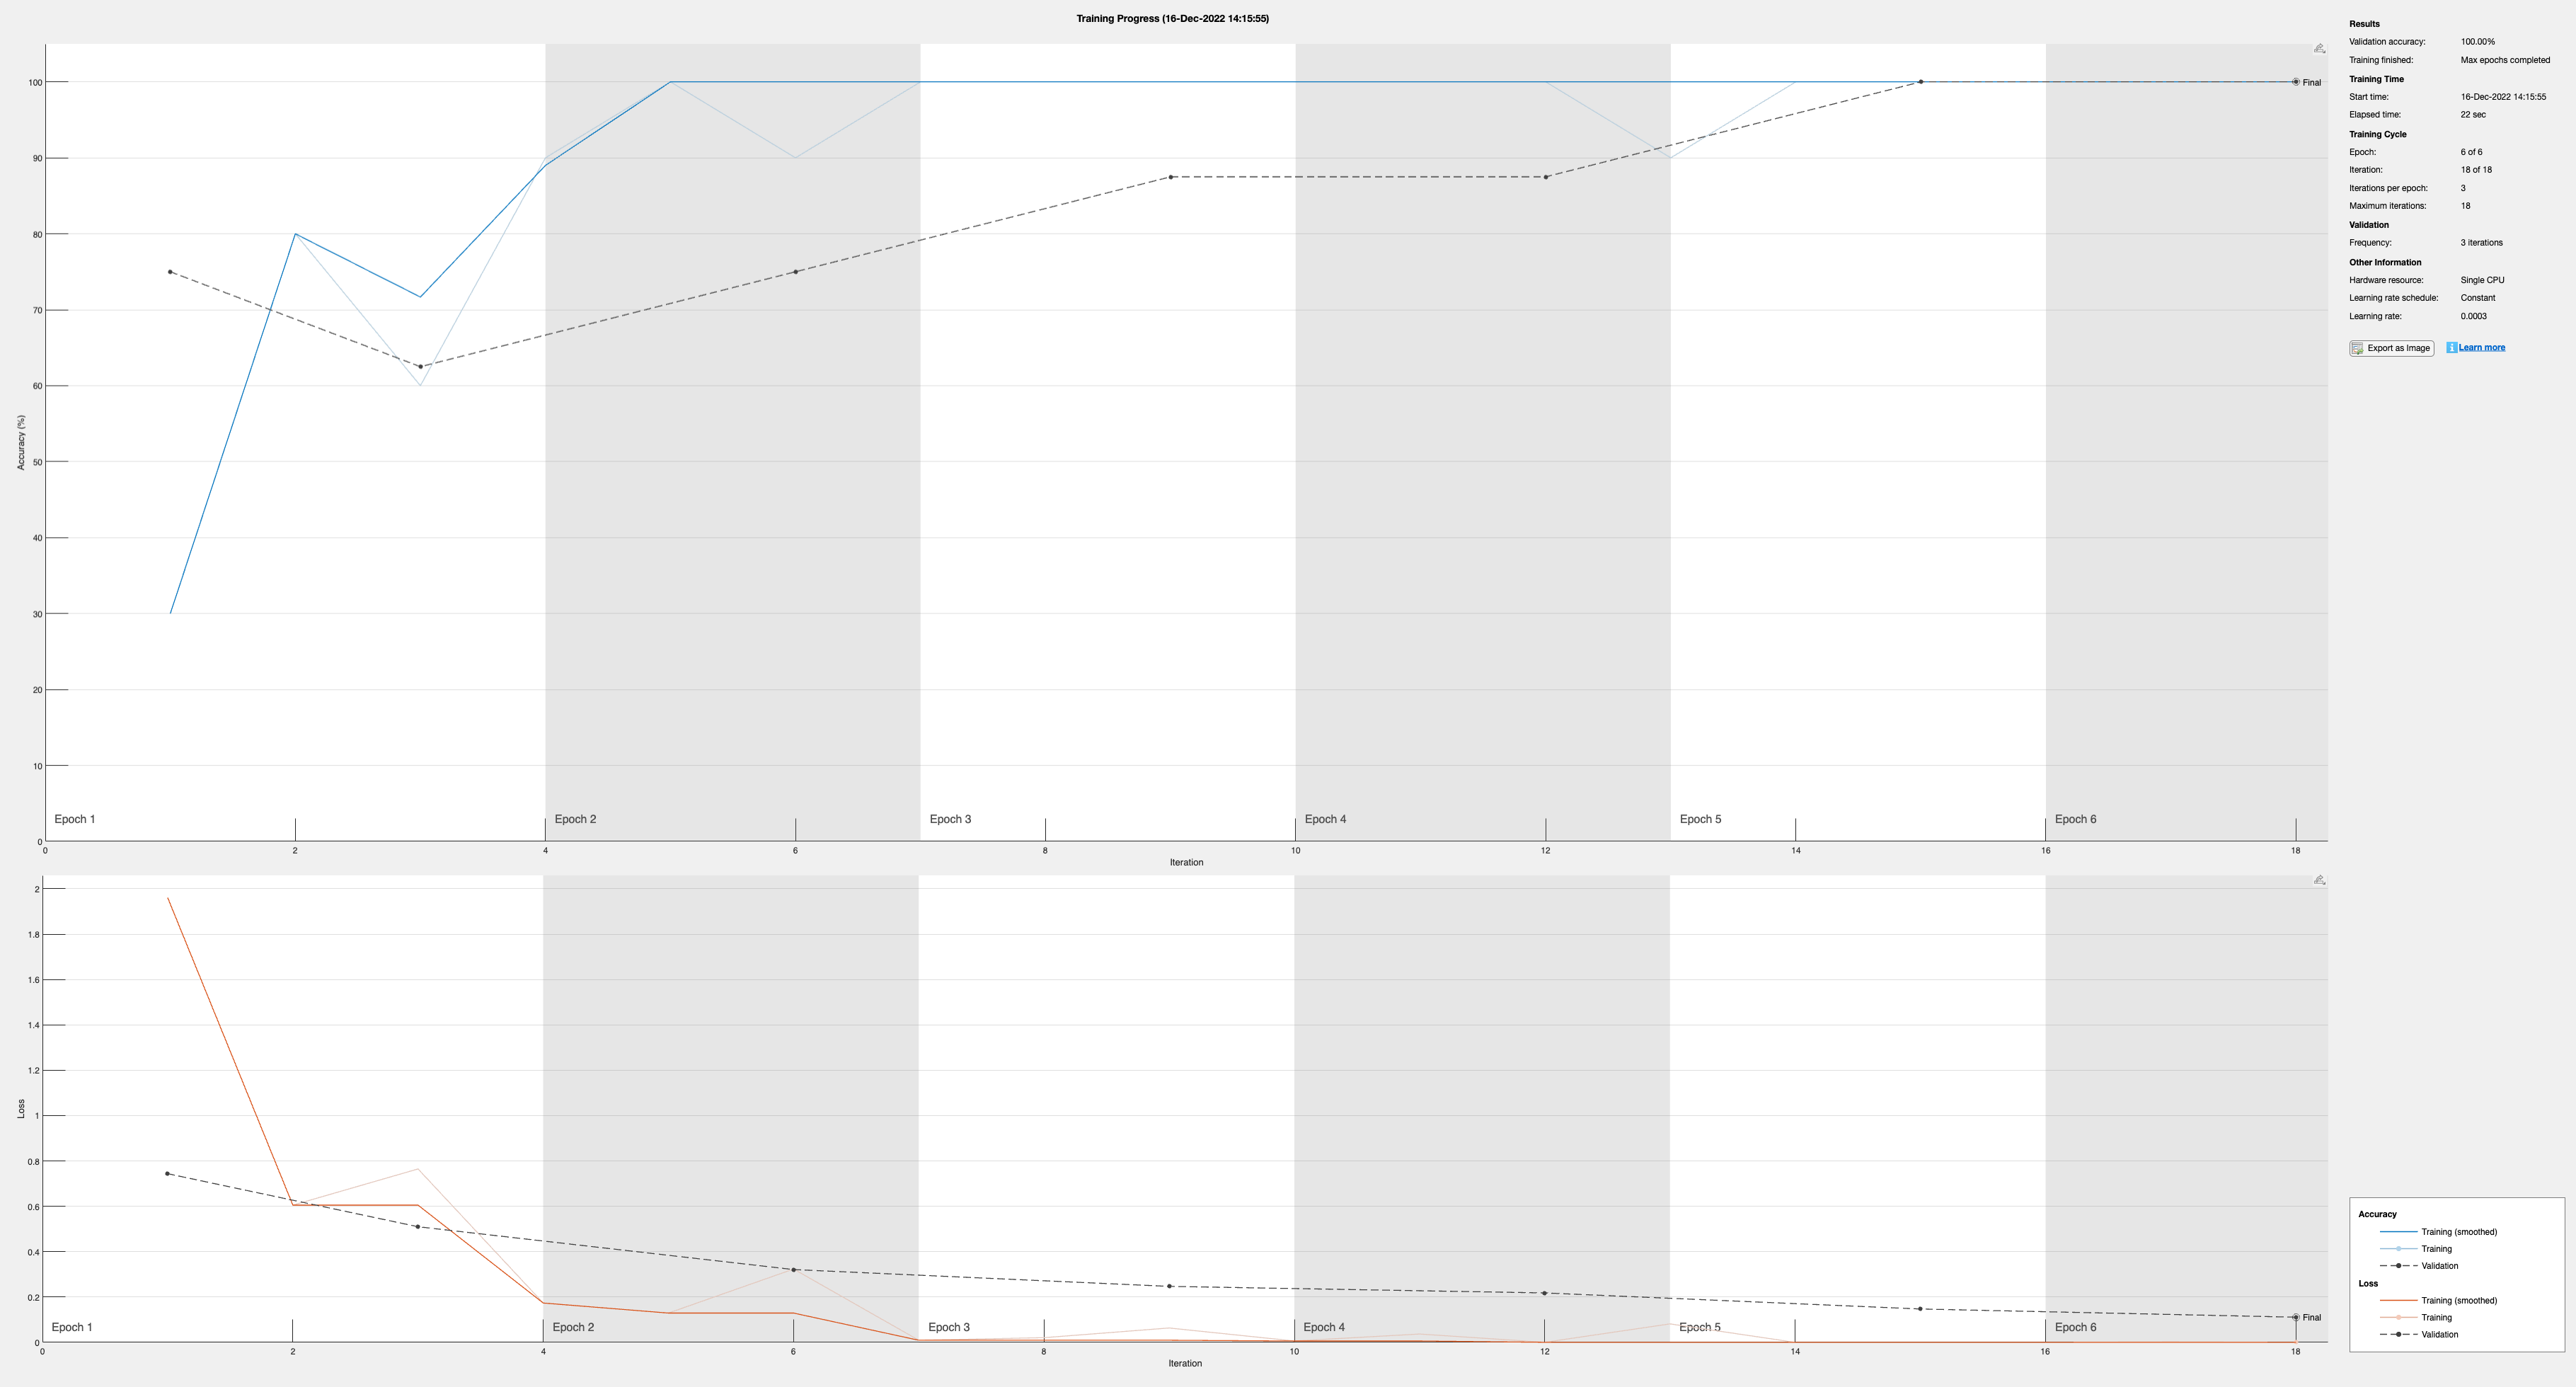

miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

net1 = trainNetwork(augimdsTrain,lgraph,options);

#### Classify Image

Load a test image containing a picture of a dog or a cat.

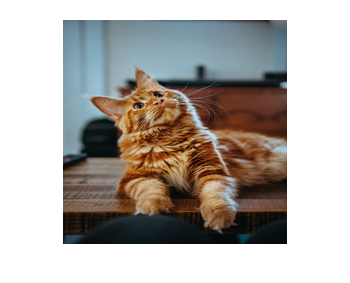

% img = imread("sherlock.jpg");
img = imread("amber.jpg");
img = imresize(img,inputSize(1:2));

figure
imshow(img)

Classify the image using the pretrained network.

[YPred,scores] = classify(net1,img);
YPred

YPred = categorical
     cat 


#### Grad-CAM

We use the gradient-weighted class activation mapping (Grad-CAM) technique to understand which parts of the image are most important for classification and display the results as an overlaid colormap on top of the original test image.

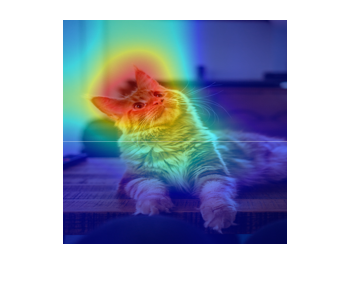

gradcamMap = gradCAM(net1,img,YPred);

imshow(img);
hold on;
imagesc(gradcamMap,'AlphaData',0.5);
colormap jet
hold off;

## Task 2: Dog breed

#### Load Data

This dataset contains 504 images corresponding to six dog breeds (Beagle, Chihuahua, Yorkshire Terrier, Siberian Husky, Labrador Retriever, and Golden Retriever). We will use 80% of the images for training and 20% for validation.

% imds = imageDatastore('DogBreedData', ...
%     'IncludeSubfolders',true, ...
%     'LabelSource','foldernames'); 
% [imdsTrain,imdsValidation] = splitEachLabel(imds,0.8);

#### Load Pretrained Network

Load a pretrained image classification network (in this example, we use GoogLeNet).

% net = googlenet;

#### Replace Final Layers

Convert the trained network to a layer graph.

% lgraph = layerGraph(net);

Find the names of the two layers to replace. 

% [learnableLayer,classLayer] = findLayersToReplace(lgraph);
% numClasses = numel(categories(imdsTrain.Labels));
% 
% if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
%     newLearnableLayer = fullyConnectedLayer(numClasses, ...
%         'Name','new_fc', ...
%         'WeightLearnRateFactor',10, ...
%         'BiasLearnRateFactor',10);
%     
% elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
%     newLearnableLayer = convolution2dLayer(1,numClasses, ...
%         'Name','new_conv', ...
%         'WeightLearnRateFactor',10, ...
%         'BiasLearnRateFactor',10);
% end
% 
% lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);
% newClassLayer = classificationLayer('Name','new_classoutput');
% lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

#### Freeze Initial Layers

% layers = lgraph.Layers;
% connections = lgraph.Connections;
% 
% layers(1:10) = freezeWeights(layers(1:10));
% lgraph = createLgraphUsingConnections(layers,connections);

#### Data Augmentation

We will use an augmented image datastore to automatically resize the training images. Additionally, we will perform several image data augmentation operations on the training images.  

% inputSize = net.Layers(1).InputSize;
% 
% pixelRange = [-30 30];
% scaleRange = [0.9 1.1];
% imageAugmenter = imageDataAugmenter( ...
%     'RandXReflection',true, ...
%     'RandXTranslation',pixelRange, ...
%     'RandYTranslation',pixelRange, ...
%     'RandXScale',scaleRange, ...
%     'RandYScale',scaleRange);
% augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
%     'DataAugmentation',imageAugmenter);

To automatically resize the validation images without performing further data augmentation, we will use an augmented image datastore without specifying any additional preprocessing operations.

% augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

#### Train Network

% miniBatchSize = 10;
% valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
% options = trainingOptions('sgdm', ...
%     'MiniBatchSize',miniBatchSize, ...
%     'MaxEpochs',6, ...
%     'InitialLearnRate',3e-4, ...
%     'Shuffle','every-epoch', ...
%     'ValidationData',augimdsValidation, ...
%     'ValidationFrequency',valFrequency, ...
%     'Verbose',false, ...
%     'Plots','training-progress');
% 
% net = trainNetwork(augimdsTrain,lgraph,options);
% save breedClassifierNet net
load breedClassifierNet.mat

#### Classify Image

Load a test image containing a picture of a dog to determine its breed.

%img = imread("sherlock.jpg");
img = imread("libby.jpg");
% Other images to try: goldie, chico, husky, libby, terry, and snoopy
img = imresize(img,inputSize(1:2));

figure
imshow(img)

Classify the image using the pretrained network.

[YPred,scores] = classify(net,img);
YPred

#### Grad-CAM

We use the gradient-weighted class activation mapping (Grad-CAM) technique to understand which parts of the image are most important for classification and display the results as an overlaid colormap on top of the original test image.

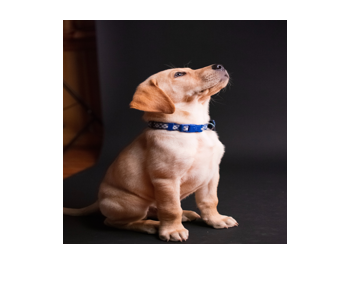

gradcamMap = gradCAM(net,img,YPred);


imshow(img);
hold on;
imagesc(gradcamMap,'AlphaData',0.5);

YPred = categorical
     beagle 


colormap jet
hold off

## Supporting Functions

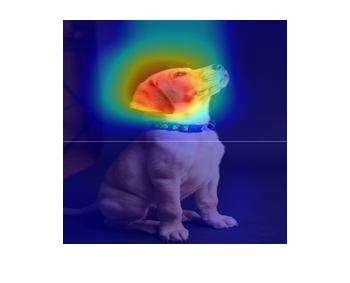

function [learnableLayer,classLayer] = findLayersToReplace(lgraph)
% findLayersToReplace(lgraph) finds the single classification layer and the
% preceding learnable (fully connected or convolutional) layer of the layer
% graph lgraph

if ~isa(lgraph,'nnet.cnn.LayerGraph')
    error('Argument must be a LayerGraph object.')

end

% Get source, destination, and layer names.
src = string(lgraph.Connections.Source);
dst = string(lgraph.Connections.Destination);
layerNames = string({lgraph.Layers.Name}');

% Find the classification layer. The layer graph must have a single
% classification layer.
isClassificationLayer = arrayfun(@(l) ...
    (isa(l,'nnet.cnn.layer.ClassificationOutputLayer')|isa(l,'nnet.layer.ClassificationLayer')), ...
    lgraph.Layers);

if sum(isClassificationLayer) ~= 1
    error('Layer graph must have a single classification layer.')
end
classLayer = lgraph.Layers(isClassificationLayer);


% Traverse the layer graph in reverse starting from the classification
% layer. If the network branches, throw an error.
currentLayerIdx = find(isClassificationLayer);
while true
    
    if numel(currentLayerIdx) ~= 1
        error('Layer graph must have a single learnable layer preceding the classification layer.')
    end
    
    currentLayerType = class(lgraph.Layers(currentLayerIdx));
    isLearnableLayer = ismember(currentLayerType, ...
        ['nnet.cnn.layer.FullyConnectedLayer','nnet.cnn.layer.Convolution2DLayer']);
    
    if isLearnableLayer
        learnableLayer =  lgraph.Layers(currentLayerIdx);
        return
    end
    
    currentDstIdx = find(layerNames(currentLayerIdx) == dst);
    currentLayerIdx = find(src(currentDstIdx) == layerNames);
    
end

end


function layers = freezeWeights(layers)
% layers = freezeWeights(layers) sets the learning rates of all the
% parameters of the layers in the layer array |layers| to zero.

for ii = 1:size(layers,1)
    props = properties(layers(ii));
    for p = 1:numel(props)
        propName = props{p};
        if ~isempty(regexp(propName, 'LearnRateFactor$', 'once'))
            layers(ii).(propName) = 0;
        end
    end
end

end


% lgraph = createLgraphUsingConnections(layers,connections) creates a layer
% graph with the layers in the layer array |layers| connected by the
% connections in |connections|.

function lgraph = createLgraphUsingConnections(layers,connections)

lgraph = layerGraph();
for i = 1:numel(layers)
    lgraph = addLayers(lgraph,layers(i));
end

for c = 1:size(connections,1)
    lgraph = connectLayers(lgraph,connections.Source{c},connections.Destination{c});
end

end